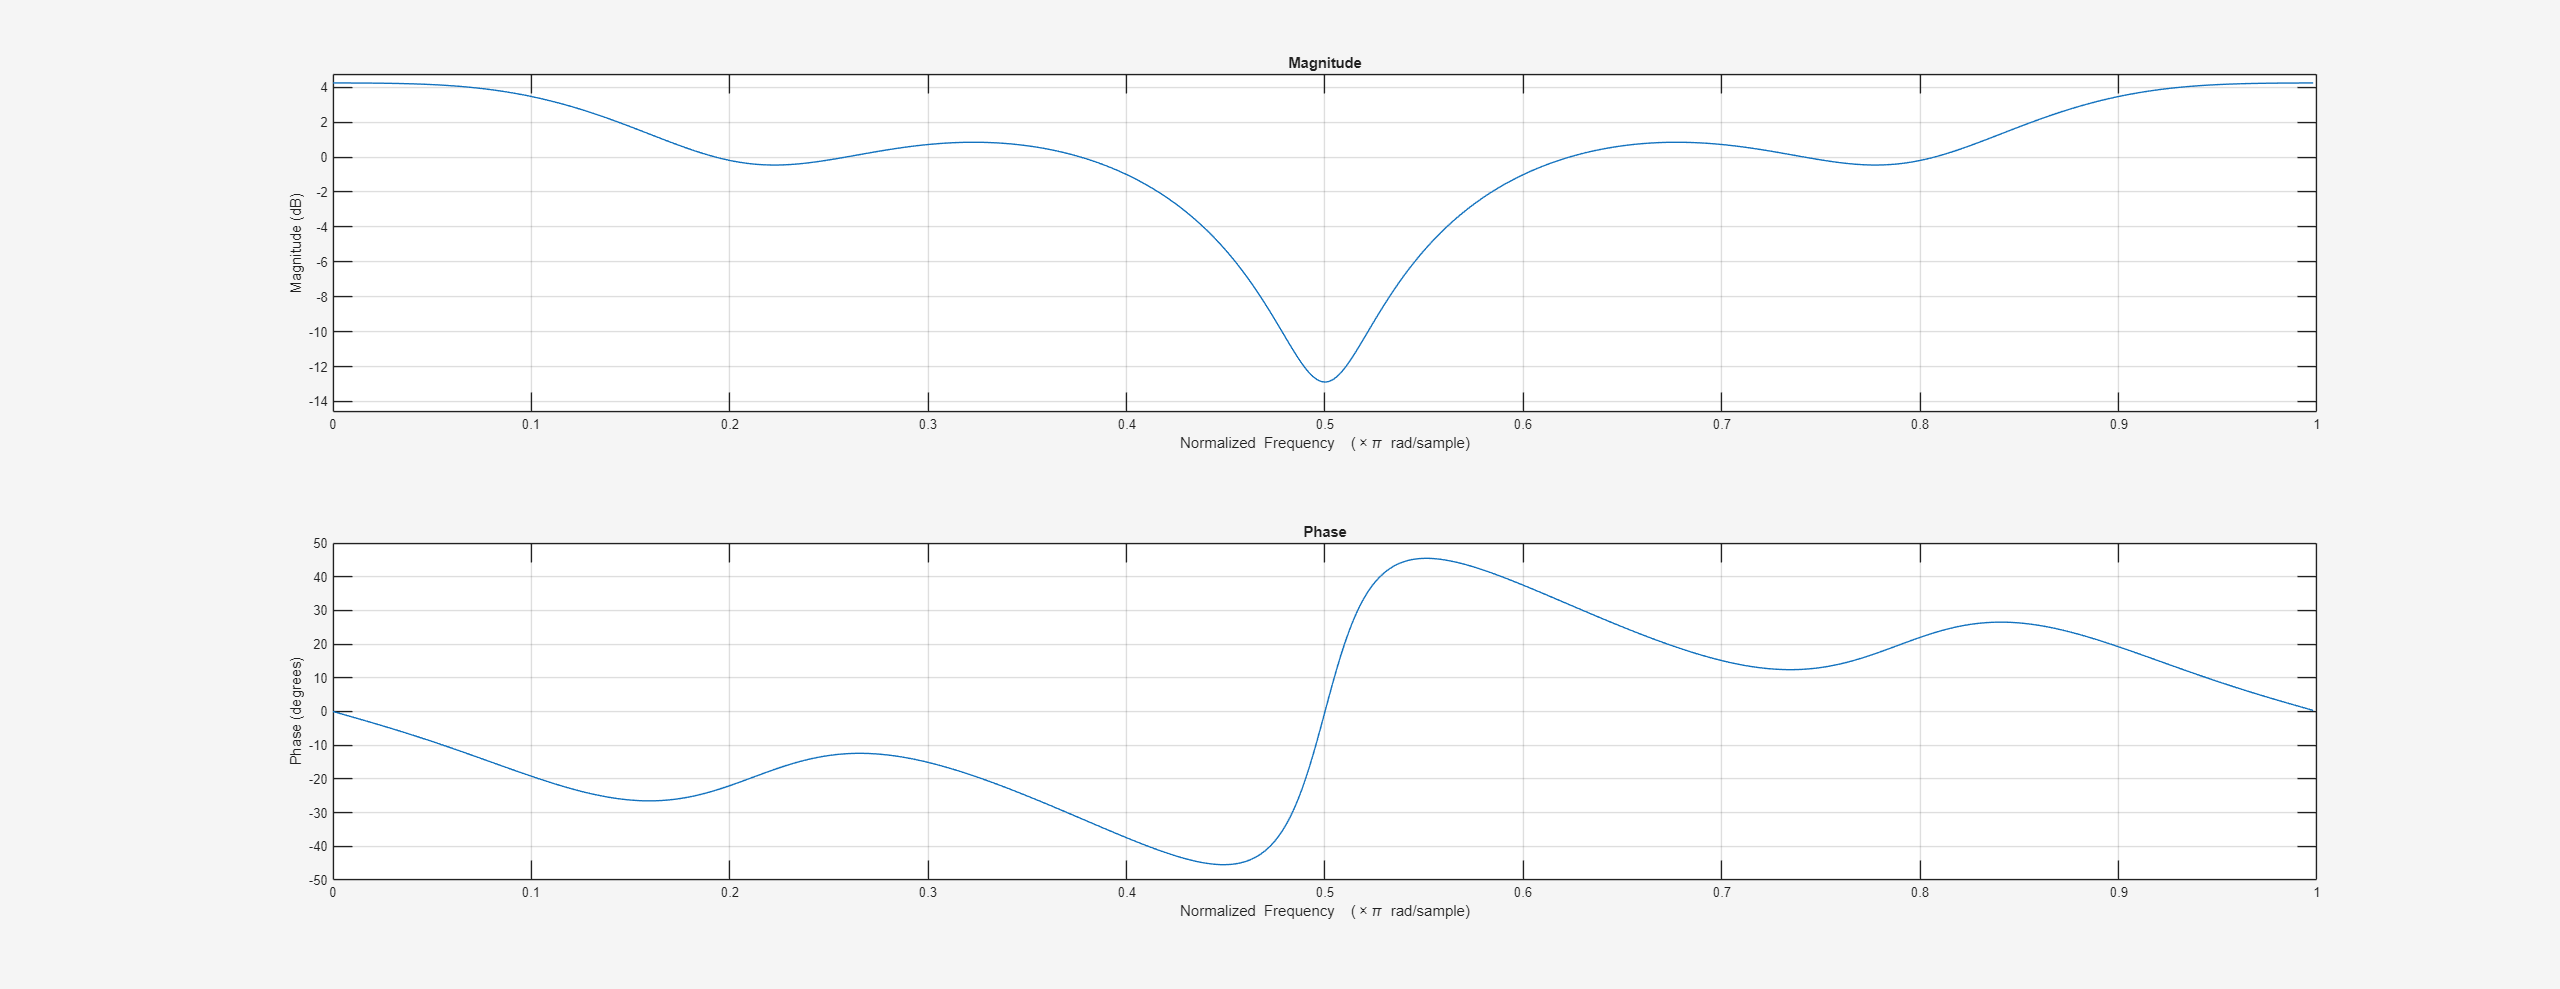



num=[1 0 0.49 0 0 0 0.2401 0 -0.0576 0 -0.0282 0 -0.0138];

den=[1];
freqz(num,den);

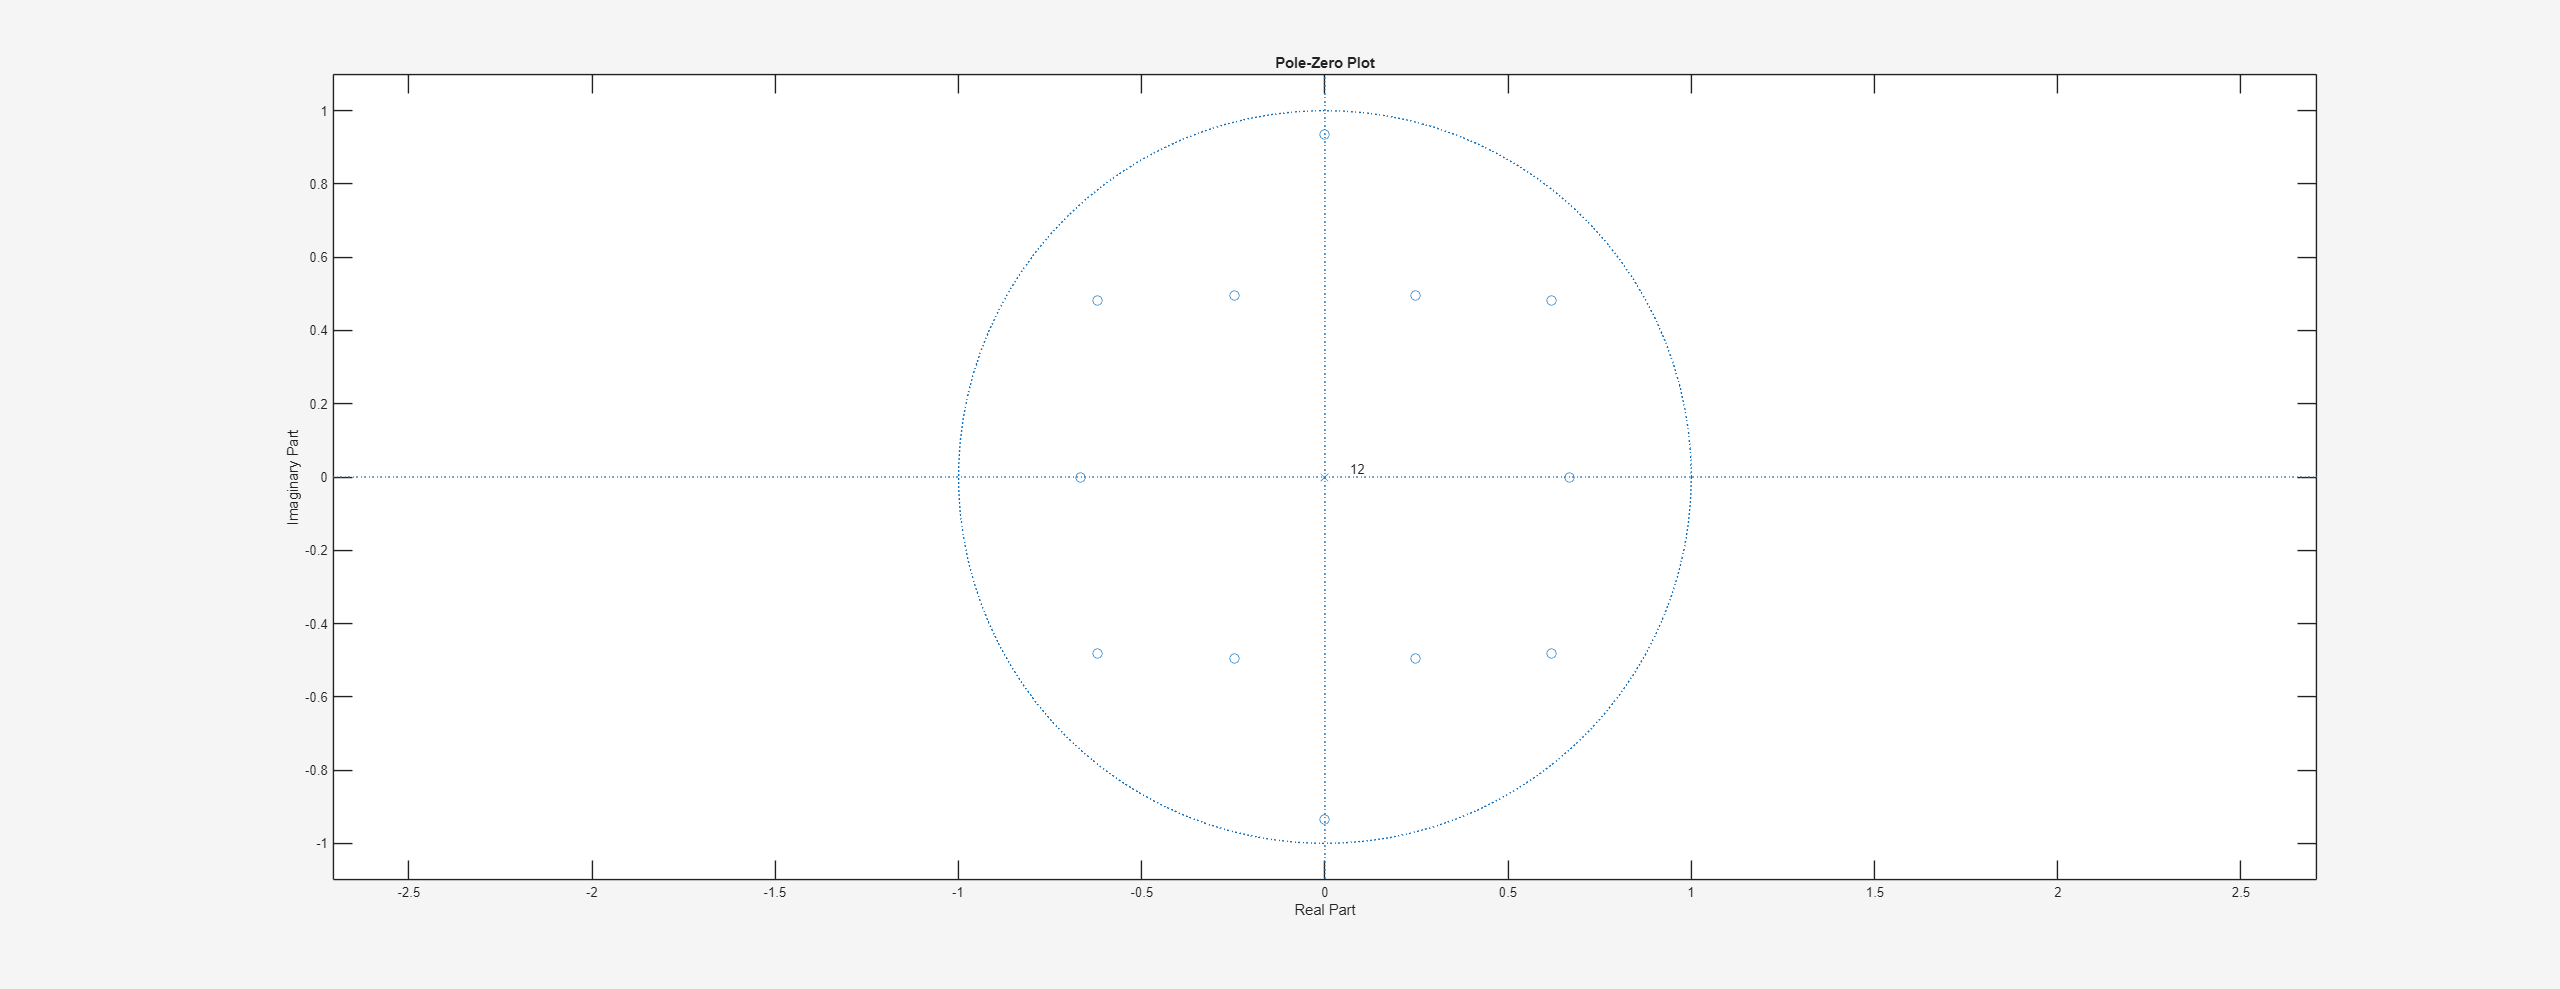

zplane(num,den);

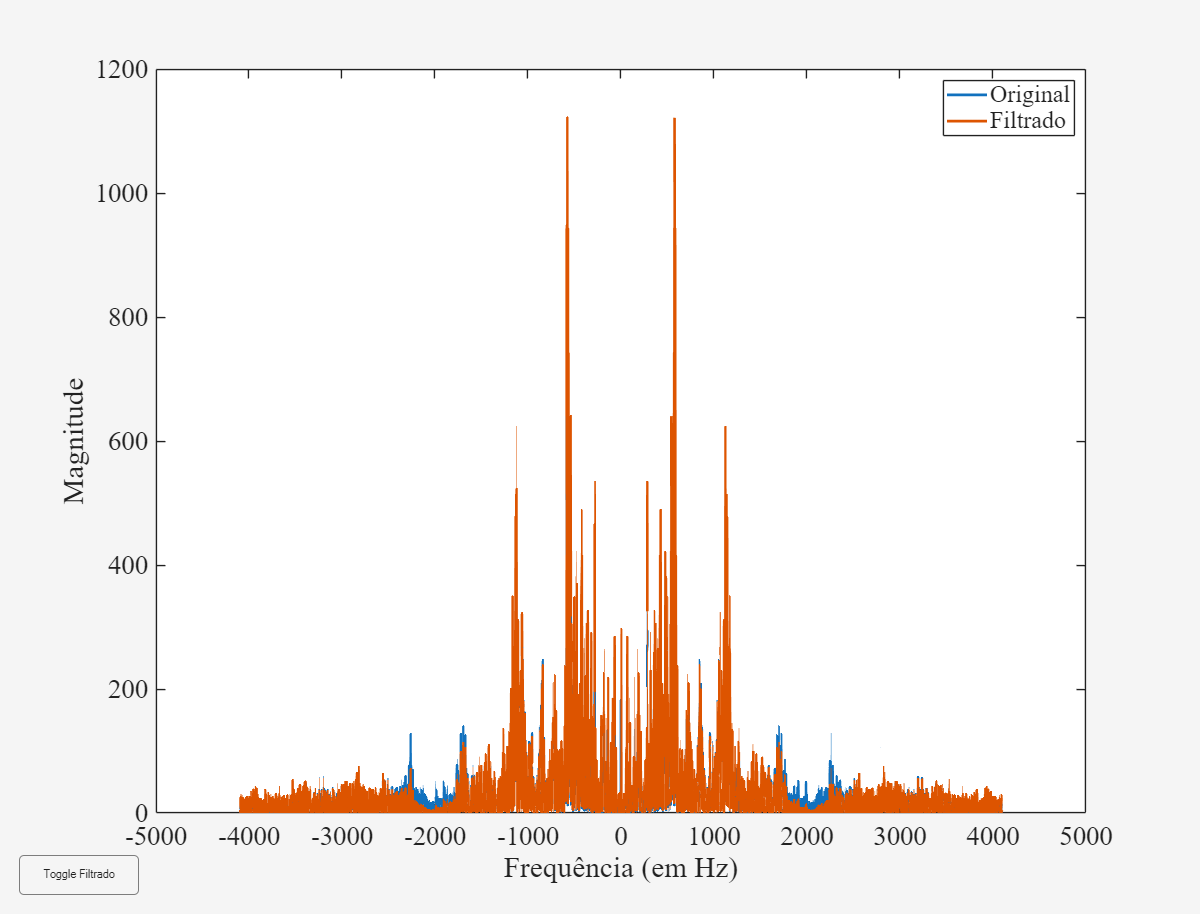

--- Avaliação da Recuperação do Sinal ---


Potência Média do Sinal Original (y):   0.038505


Potência Média do Sinal Filtrado (yn):  0.057339


Porcentagem de Sinal Recuperado: 148.91%


load handel.mat
num=[1 0 0.49 0 0 0 0.2401 0 -0.0576 0 -0.0282 0 -0.0138];
den=[1];
yn = filter(num,den,y);

% Plot inicial
h1 = spectrumAnalyzermod(y,Fs,1,800); hold on;
h2 = spectrumAnalyzermod(yn,Fs,0,800);

legend('Original','Filtrado');

% >>> Fixar limites para não mudar quando esconder
xlim([-5000 5000])
ylim([0 1200])


% Criar botão para ligar/desligar a curva filtrada
uicontrol('Style','pushbutton','String','Toggle Filtrado',...
    'Position',[20 20 120 40],...
    'Callback',@(src,~) toggleVisibility(h2));

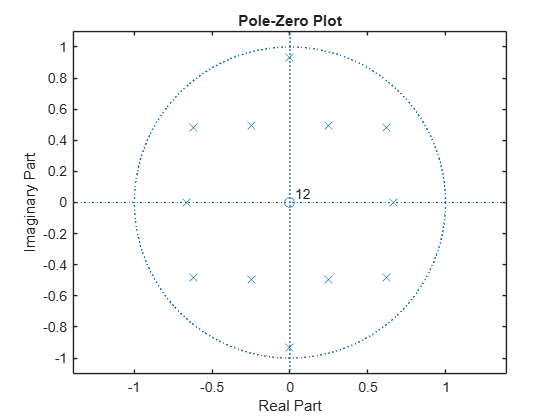

num=[1 0 0.49 0 0 0 0.2401 0 -0.0576 0 -0.0282 0 -0.0138];
den=[1];

figure;
zplane(den,num);

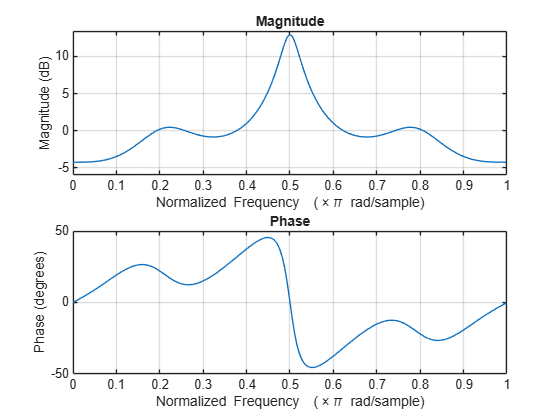

freqz(den,num);

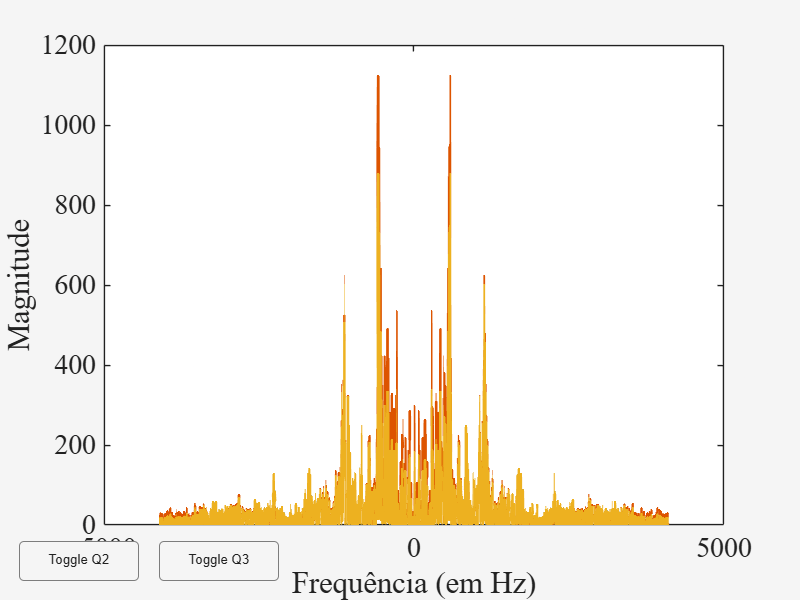

load handel.mat
yn=filter(num,den,y);
y_rec=filter(den,num,yn);

%comparacao entre sinal original, sinal filtrado e sinal recuperado
spectrumAnalyzermod(y,Fs,1,800); hold on;
p2=spectrumAnalyzermod(yn,Fs,0,800);
p3=spectrumAnalyzermod(y_rec,Fs,0,800);
xlim([-5000 5000])
ylim([0 1200])

% Botão 1 -> liga/desliga h2
uicontrol('Style','pushbutton','String','Toggle Q2',...
    'Position',[20 20 120 40],...
    'Callback',@(src,~) toggleVisibility(p2));

% Botão 2 -> liga/desliga h3
uicontrol('Style','pushbutton','String','Toggle Q3',...
    'Position',[160 20 120 40],...
    'Callback',@(src,~) toggleVisibility(p3));

yn=y_rec;
if length(y) > length(yn)
    y = y(1:length(yn));
elseif length(yn) > length(y)
    yn = yn(1:length(y));
end


energia_y = sum(y.^2);



energia_yn = sum(yn.^2);

if energia_yn > 0
    porcentagem_recuperada = (energia_yn / energia_y) * 100;

    disp('--- Avaliação da Recuperação do Sinal ---');
    disp(['energia  do Sinal Original (y):   ', num2str(energia_y)]);
    disp(['energia  do Sinal Filtrado (yn):  ', num2str(energia_yn)]);
    disp(['Porcentagem de Sinal Recuperado: ', num2str(porcentagem_recuperada, '%.2f'), '%']);
 
end 

--- Avaliação da Recuperação do Sinal ---


energia  do Sinal Original (y):   2815.2472


energia  do Sinal Filtrado (yn):  2815.2472


Porcentagem de Sinal Recuperado: 100.00%


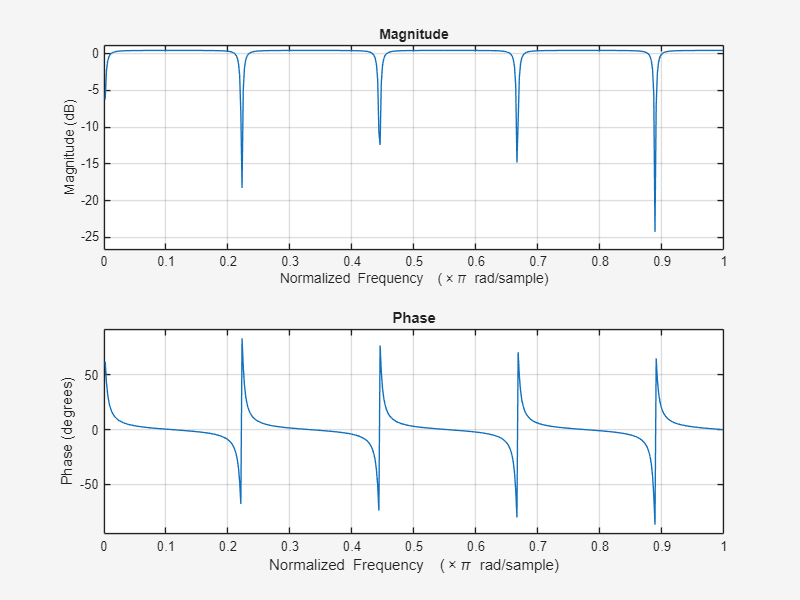

a=0.9; L=9;
num=zeros(1,L+1);
num(1)=1;
num(L+1)=-1;
den=zeros(1,L+1);
den(1)=1;
den(L+1)=-a;

freqz(num,den);

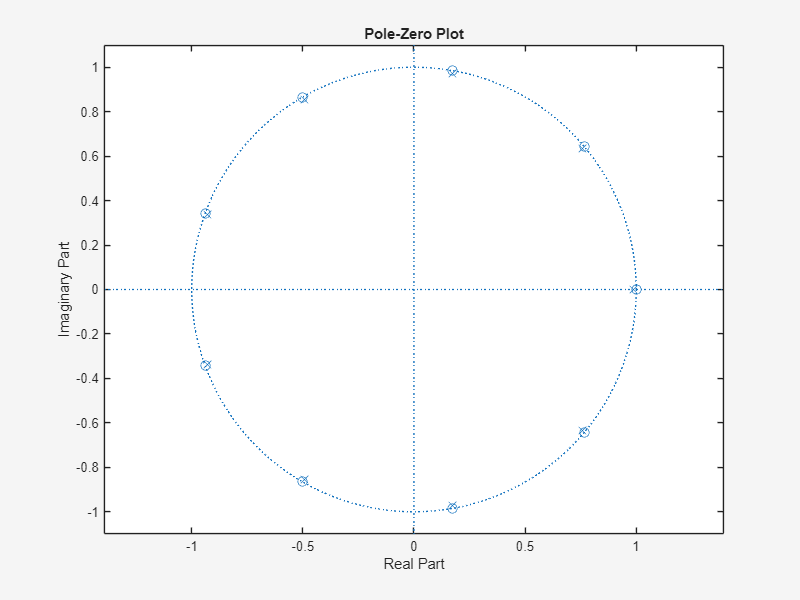

zplane(num,den);

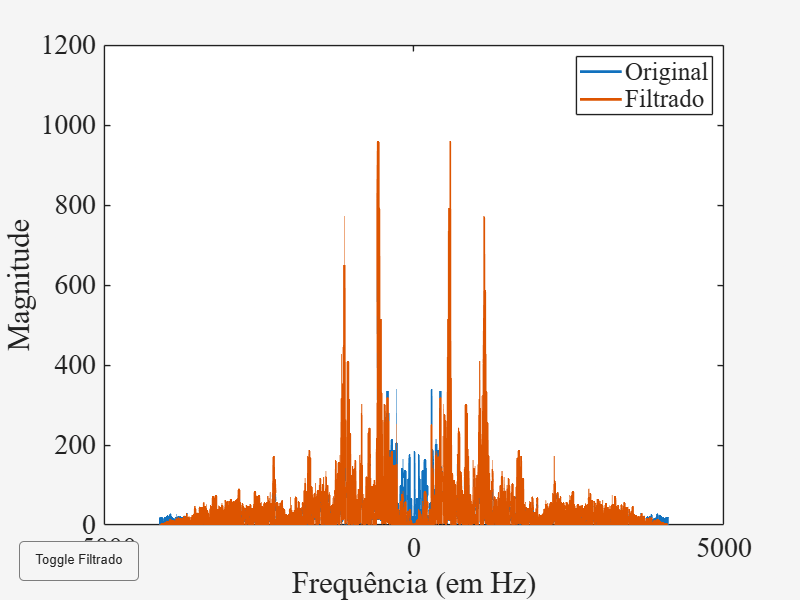

load handel.mat
a=0.5; L=2;
a=0.5; L=2;

num = [1 zeros(1,L-1) -1];
den = [1 zeros(1,L-1) -a];
yn = filter(num,den,y);
%sound(y,Fs);
%pause(9);
%sound(yn,Fs);
% Plot inicial
h1 = spectrumAnalyzermod(y,Fs,1,800); hold on;
h2 = spectrumAnalyzermod(yn,Fs,0,800);

legend('Original','Filtrado');

% >>> Fixar limites para não mudar quando esconder
xlim([-5000 5000])
ylim([0 1200])


% Criar botão para ligar/desligar a curva filtrada
uicontrol('Style','pushbutton','String','Toggle Filtrado',...
    'Position',[20 20 120 40],...
    'Callback',@(src,~) toggleVisibility(h2));

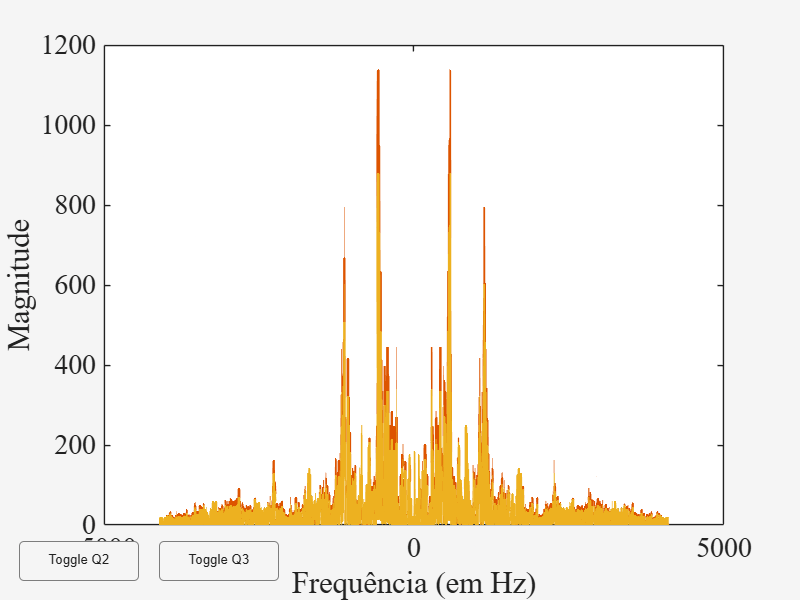

load handel.mat 
a = 0.5; 
L = 10;

% --- Sistema que distorce ---
num = [1 zeros(1,L-1) -1];
den = [1 zeros(1,L-1) -a];
y_n = filter(num,den,y);   % sinal distorcido

% --- Filtro recuperador (inverso) ---
num_rec = [1 zeros(1,L-1) -a];
den_rec = [1 zeros(1,L-1) -1];
y_rec = filter(num_rec, den_rec, y_n);  % sinal recuperado














spectrumAnalyzermod(y,Fs,1,800); hold on;
p2=spectrumAnalyzermod(y_n,Fs,0,800);
p3=spectrumAnalyzermod(y_rec,Fs,0,800);
xlim([-5000 5000])
ylim([0 1200])
% Botão 1 -> liga/desliga h2
uicontrol('Style','pushbutton','String','Toggle Q2',...
    'Position',[20 20 120 40],...
    'Callback',@(src,~) toggleVisibility(p2));

% Botão 2 -> liga/desliga h3
uicontrol('Style','pushbutton','String','Toggle Q3',...
    'Position',[160 20 120 40],...
    'Callback',@(src,~) toggleVisibility(p3));

yn=y_rec;
if length(y) > length(yn)
    y = y(1:length(yn));
elseif length(yn) > length(y)
    yn = yn(1:length(y));
end


energia_y = sum(y.^2);



energia_yn = sum(yn.^2);


if energia_yn > 0
    porcentagem_recuperada = (energia_yn / energia_y) * 100;

    disp('--- Avaliação da Recuperação do Sinal ---');
    disp(['energia  do Sinal Original (y):   ', num2str(energia_y)]);
    disp(['energia  do Sinal Filtrado (yn):  ', num2str(energia_yn)]);
    disp(['Porcentagem de Sinal Recuperado: ', num2str(porcentagem_recuperada, '%.2f'), '%']);
 
end 

--- Avaliação da Recuperação do Sinal ---


energia  do Sinal Original (y):   2815.2472


energia  do Sinal Filtrado (yn):  2815.2472


Porcentagem de Sinal Recuperado: 100.00%


questao 7

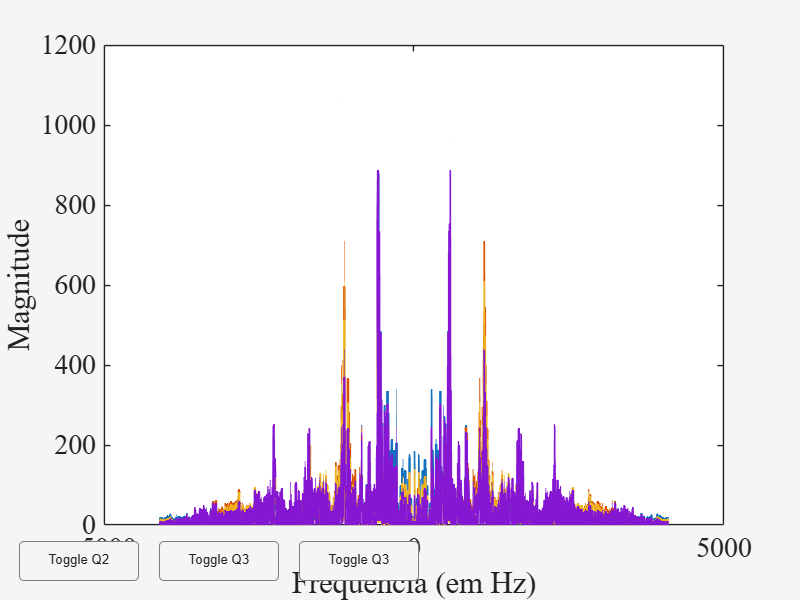

clear;
load handel.mat


num=[1 0 0.49 0 0 0 0.2401 0 -0.0576 0 -0.0282 0 -0.0138];
den=[1 zeros(1,12)];
yn = filter(num,den,y);

% Exibir os resultados
iteracoes=50;

soma_zeros_adicionados = (iteracoes * (iteracoes + 1)) / 2;
tam_den_f_max = length(den)+soma_zeros_adicionados;
tam_coluna_max = tam_den_f_max - length(num) + 1;
qp = zeros(iteracoes, tam_coluna_max); 
den_f=den;

for k = 1:iteracoes
[quo,den_f]=deconv(den_f,num);

qp(k,:) = [quo zeros(1, tam_coluna_max- length(quo))]; % Preenche até 22 colunas
den_f=[ den_f zeros(1,k)];
end
qt=0;
for k=1:iteracoes
    qt=qt+qp(k,:);
end


filtro1=[qt(1:3)];
filtro2=[qt(1:5)];
filtro3=[qt(1:7)];

 yo=[filter(filtro1,num,yn) filter(filtro2,num,yn) filter(filtro3,num,yn) ];
 

spectrumAnalyzermod(y,Fs,1,800); hold on;
p2=spectrumAnalyzermod(yo(:,1),Fs,0,800);
p3=spectrumAnalyzermod(yo(:,2),Fs,0,800);
p4=spectrumAnalyzermod(yo(:,3),Fs,0,800);
xlim([-5000 5000])
ylim([0 1200])
% Botão 1 -> liga/desliga h2
uicontrol('Style','pushbutton','String','Toggle Q2',...
    'Position',[20 20 120 40],...
    'Callback',@(src,~) toggleVisibility(p2));

% Botão 2 -> liga/desliga h3
uicontrol('Style','pushbutton','String','Toggle Q3',...
    'Position',[160 20 120 40],...
    'Callback',@(src,~) toggleVisibility(p3));
% Botão 2 -> liga/desliga h4
uicontrol('Style','pushbutton','String','Toggle Q3',...
    'Position',[300 20 120 40],...
    'Callback',@(src,~) toggleVisibility(p4));

y1=yo(:,1);
y2=yo(:,2);
y3=yo(:,3);

for k=1:3
yn=yo(:,k);
% Se o seu sinal 'y' for muito grande ou infinito, a filtragem pode produzir
% um vetor 'yn' maior ou de tamanho diferente. É fundamental que ambos tenham
% o mesmo tamanho para este cálculo. 
% Se eles tiverem tamanhos diferentes, você deve truncar o maior 
% para o tamanho do menor, ou considerar apenas a parte estacionária do sinal.
if length(y) > length(yn)
    y = y(1:length(yn));
elseif length(yn) > length(y)
    yn = yn(1:length(y));
end


energia_y = sum(y.^2);


energia_yn = sum(yn.^2);

if energia_yn > 0
    porcentagem_recuperada = (energia_yn / energia_y) * 100;

    disp('--- Avaliação da Recuperação do Sinal ---');
    disp(['energia  do Sinal Original (y):   ', num2str(energia_y)]);
    disp(['energia  do Sinal Filtrado (yn):  ', num2str(energia_yn)]);
    disp(['Porcentagem de Sinal Recuperado: ', num2str(porcentagem_recuperada, '%.2f'), '%']);
 
end 
end

--- Avaliação da Recuperação do Sinal ---


energia  do Sinal Original (y):   2815.2472


energia  do Sinal Filtrado (yn):  2582.7974


Porcentagem de Sinal Recuperado: 91.74%


--- Avaliação da Recuperação do Sinal ---


energia  do Sinal Original (y):   2815.2472


energia  do Sinal Filtrado (yn):  2101.0978


Porcentagem de Sinal Recuperado: 74.63%


--- Avaliação da Recuperação do Sinal ---


energia  do Sinal Original (y):   2815.2472


energia  do Sinal Filtrado (yn):  2574.0787


Porcentagem de Sinal Recuperado: 91.43%
